# 曲线之间填充

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

- 函数与 x 轴围成的区域填充；

- 函数之间围成的区域填充；

- 可选函数：fill、patch

#### 函数与 x 轴围成区域填充演示：

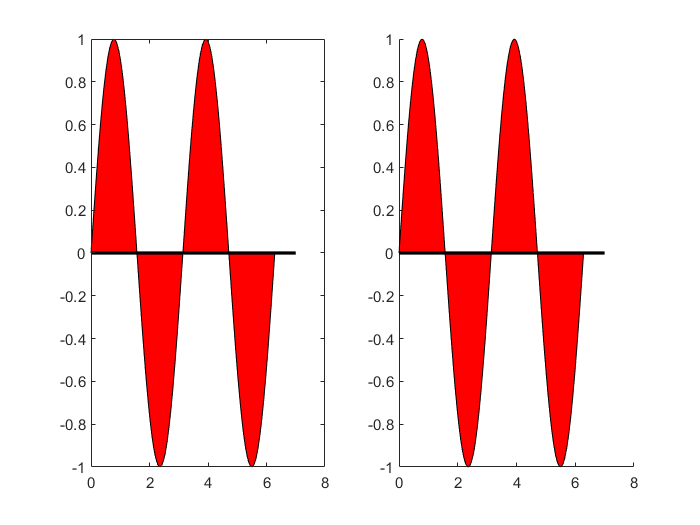

clear;clc;
% 生成数据
x1 = linspace(0, 2*pi, 100);
y1 = sin(2*x1);
figure
subplot(1, 2, 1)
fill(x1, y1, 'r'); 
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off
subplot(1, 2, 2)
patch(x1, y1, 'r'); 
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off

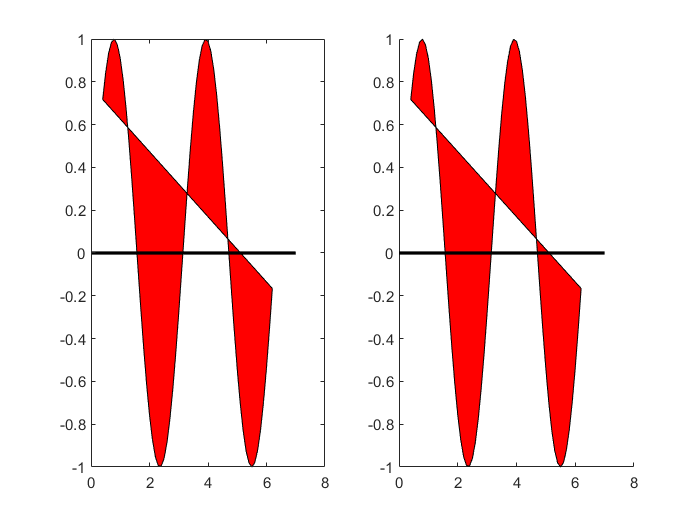

% 换一下数据
x2 = 0.4:0.1:2*pi;
y2 = sin(2*x2);
figure
subplot(1, 2, 1)
fill(x2, y2, 'r');
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off
subplot(1, 2, 2)
patch(x2, y2, 'r'); 
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off

#### 这个结果似乎没有达到预期，查询到 fill 和 patch 函数是做的多边形填充，因此需要做一些修改。

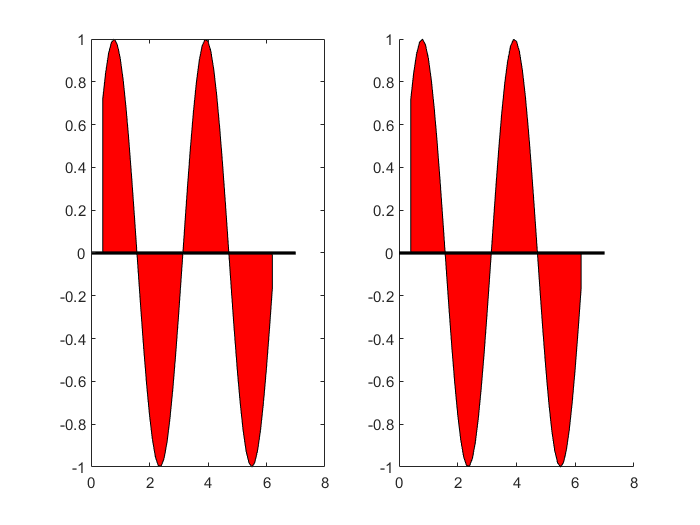

% 强制首尾各添加一个点，保证 y 值为 0
x3 = [x2(1), x2, x2(end)];
y3 = [0, y2, 0];
figure
subplot(1, 2, 1)
fill(x3, y3, 'r');
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off
subplot(1, 2, 2)
patch(x3, y3, 'r'); 
hold on
plot([0, 7], [0, 0], 'k', 'LineWidth', 2);
hold off

#### 函数之间围成的区域填充演示：

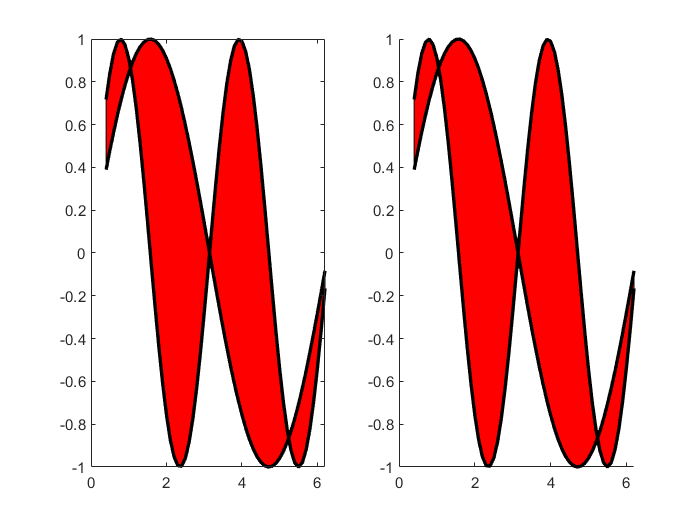

y4 = sin(x2);
% 确定 y2 和 y4 的上下边界
maxY = max([y2; y4]);
minY = min([y2; y4]);
% 确定填充多边形，按照顺时针方向来确定点
% fliplr 实现左右翻转
xFill = [x2, fliplr(x2)];
yFill = [maxY, fliplr(minY)];
figure
subplot(1, 2, 1)
fill(xFill, yFill, 'r');
hold on
plot(x2, y2, 'k', 'LineWidth', 2)
plot(x2, y4, 'k', 'LineWidth', 2)
hold off
subplot(1, 2, 2)
patch(xFill, yFill, 'r'); 
hold on
plot(x2, y2, 'k', 'LineWidth', 2)
plot(x2, y4, 'k', 'LineWidth', 2)
hold off